# Outlier Detection and Confidence Intervals

Data Science for Engineers II

WS 2024\25

Dimitar Ninevski

## Prepare workspace

close all;
clear;

## Load data

We will load the dataset varKept.mat

load('varKept.mat');

## Compute outliers using IQR

First we will visualize the boxplot.

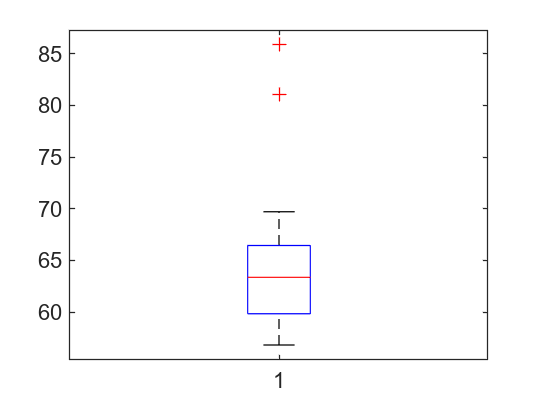

figBoxPlot = figure;
boxplot(varKept)

Let's compute which days are outliers.

We need to compute q25, q75 and IQR.

iqrData = iqr(varKept);
q25 = quantile(varKept, .25);
q75 = quantile(varKept, .75);
medianData = median(varKept);

Compute the boundaries for outlier detection

coeff = 1.5;
upB = q75 + coeff*iqrData;
loB = q25 - coeff*iqrData;

Compute the boolean vector

outBool = (varKept > upB) + (varKept < loB);

Determine the indices of the outliers.

find(outBool~=0)

ans =      2
     3


## Plot the data

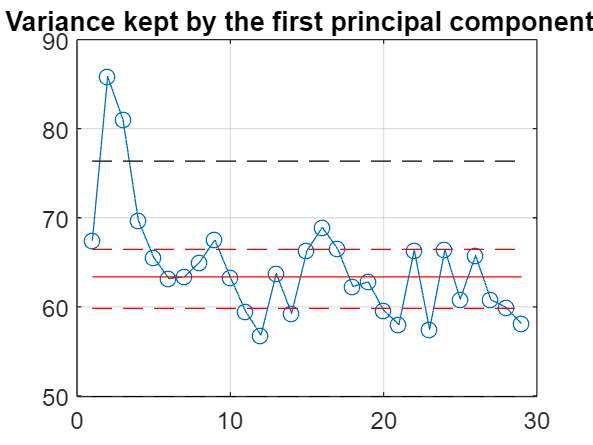

fig1 = figure;
plot(varKept, '-o')
hold on
% Plot horizontal lines for median and quantiles
plot([1, length(varKept)], [medianData, medianData], 'r');
plot([1, length(varKept)], [q25, q25], 'r--');
plot([1, length(varKept)], [q75, q75], 'r--');
plot([1, length(varKept)], [upB, upB], 'k--');
plot([1, length(varKept)], [loB, loB], 'k--');
grid on;
title('Variance kept by the first principal components');

## Compute the mean and standard deviation

meanData = mean(varKept);
stdData = std(varKept);

## Plot the mean and std values

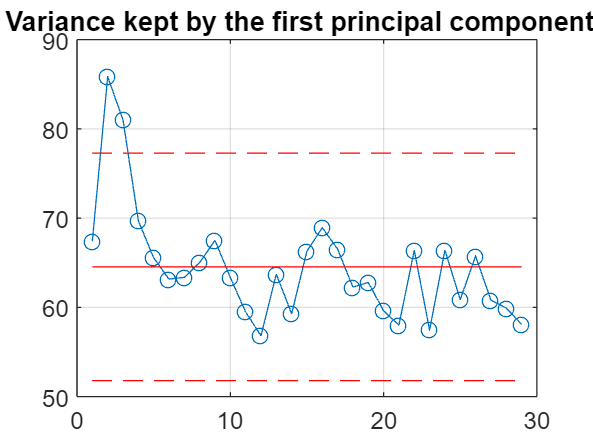

figConfidence = figure;
plot(varKept, '-o')
hold on
% Plot horizontal lines for mean and standard deviation
plot([1, length(varKept)], [meanData, meanData], 'r');
plot([1, length(varKept)], [meanData + 2*stdData, meanData + 2*stdData], 'r--');
plot([1, length(varKept)], [meanData - 2*stdData, meanData - 2*stdData], 'r--');
grid on;
title('Variance kept by the first principal components');